%% test4.1.m  修正版
% 说明：特征列统一用 1:6（第 7 列标签不读），标签按工作表名自动确定
clear; clc; close all;

%% 1. 参数设置
modelFile      = 'motor_cnn_model7.mat';       % 新模型
dataFiles      = { ...                         % 测试文件列表
    'E:\FILE2\sheffeild\毕设\TraindataH1.xlsx';
    'E:\FILE2\sheffeild\毕设\TraindataU1.xlsx';
    'E:\FILE2\sheffeild\毕设\TraindataU2.xlsx';
    'E:\FILE2\sheffeild\毕设\TraindataU3.xlsx';
    };
outputDir      = 'E:\FILE2\sheffeild\毕设\测试结果';
sampleRatio    = 0.8;      % 抽样比例
wallRanges     = [ ...     % 墙区间
    0, 5;
    67000, 67007;
    134000, 134010
    ];
selectedCols   = 1:6;      % 只用前 6 列特征（第 7 列标签不用）
startRow       = 2001;     % 跳过前 N 行

%% 2. 输出目录
if ~exist(outputDir,'dir'), mkdir(outputDir); end

%% 3. 加载模型 + 归一化参数
fprintf('加载模型与归一化参数...\n');

加载模型与归一化参数...


load(modelFile,'net','modelInfo');
global_mean = modelInfo.global_mean(:)';   % 1×6
global_std  = modelInfo.global_std(:)';
windowSize  = modelInfo.windowSize;
stepSize    = modelInfo.stepSize;
classNames  = net.Layers(end).ClassNames;  % 模型类别顺序
fprintf('  全局均值: %s\n', mat2str(global_mean,4));

  全局均值: [1.838e-09 6.16e-09 1.265e-10 0.004682 -0.003946 -0.0007365]


fprintf('  全局方差: %s\n', mat2str(global_std ,4));

  全局方差: [4.934e-05 4.921e-05 4.914e-05 5.949 5.949 5.948]


fprintf('  窗口大小: %d, 步长: %d\n', windowSize, stepSize);

  窗口大小: 500, 步长: 250


fprintf('  类别顺序: %s -> %s\n', classNames{1}, classNames{2});

  类别顺序: Healthy -> Faulty



%% 4. 初始化
XAll = []; YAll = []; totalWin = 0;

%% 5. 通用导入选项
opts = detectImportOptions(dataFiles{1});
opts.VariableNamingRule = 'preserve';
opts.VariableTypes(1:6) = {'double'};   % 只读 6 列特征
opts.DataRange = 'A2';                  % 跳过表头

%% 6. 逐文件/工作表处理
fprintf('开始处理 %d 个文件...\n', numel(dataFiles));

开始处理 4 个文件...


for f = 1:numel(dataFiles)
    dataPath = dataFiles{f};
    [~,fileName] = fileparts(dataPath);
    fprintf('\n文件 %d/%d : %s\n', f, numel(dataFiles), fileName);
    
    sheets = sheetnames(dataPath);
    for s = 1:numel(sheets)
        sheetName = sheets{s};
        fprintf('  工作表 %d/%d : %s\n', s, numel(sheets), sheetName);
        
        % 6.1 工作表名 -> 标签
        if contains(sheetName,'Healthy','IgnoreCase',true)
            label = "Healthy";
        else
            label = "Faulty";
        end
        
        % 6.2 读整张表
        try
            totalData = readtable(dataPath,'Sheet',sheetName,'VariableNamingRule','preserve');
            if size(totalData,1) < startRow, continue; end
            totalRows = size(totalData,1);
            fprintf('    总行数: %d\n', totalRows);
        catch ME
            fprintf('    读取失败: %s\n', ME.message);
            continue;
        end
        
        % 6.3 抽样块 + 避开墙
        blockSize = floor(totalRows * sampleRatio);
        if blockSize < windowSize, blockSize = windowSize; end
        maxStart  = totalRows - blockSize + 1;
        if maxStart < 1
            fprintf('    数据不足，跳过\n');
            continue;
        end
        
        validStarts = [];
        for st = 1:stepSize*10:maxStart
            ed = st + blockSize - 1;
            valid = true;
            for w = 1:size(wallRanges,1)
                if st <= wallRanges(w,2) && ed >= wallRanges(w,1)
                    valid = false; break;
                end
            end
            if valid, validStarts(end+1) = st; end
        end
        if isempty(validStarts)
            for st = 1:stepSize:maxStart
                ed = st + blockSize - 1;
                valid = true;
                for w = 1:size(wallRanges,1)
                    if st <= wallRanges(w,2) && ed >= wallRanges(w,1)
                        valid = false; break;
                    end
                end
                if valid, validStarts(end+1) = st; end
            end
        end
        if isempty(validStarts)
            fprintf('    无法避开墙，跳过\n');
            continue;
        end
        startIdx = validStarts(randi(numel(validStarts)));
        endIdx   = startIdx + blockSize - 1;
        % 6.4 读取数据块 (列 1-6)
        rangeStr = sprintf('A%d:F%d', startIdx, endIdx);
        opts = detectImportOptions(dataPath, 'NumVariables', 6, ...
                                   'Sheet', sheetName, ...
                                   'DataRange', rangeStr);
        
        % 强制指定 6 列类型
        opts = setvartype(opts, 1:6, 'double');
        
        try
            dataBlock = readtable(dataPath, opts);
            dataBlock = table2array(dataBlock);
        catch ME
            fprintf('    读取数据块失败: %s\n', ME.message);
            continue;
        end
        
        % 6.5 数据修复：NaN/Inf → 中位数
        mask = isnan(dataBlock) | isinf(dataBlock);
        if any(mask(:))
            fprintf('    发现 %d 个 NaN/Inf，使用中位数修复\n', sum(mask(:)));
            for c = 1:size(dataBlock,2)
                col = dataBlock(:,c);
                bad = mask(:,c);
                col(bad) = median(col(~bad),'omitnan');
                dataBlock(:,c) = col;
            end
        end
        
        % 6.6 标准化：使用训练时的全局参数
        dataBlock = (dataBlock - global_mean) ./ global_std;
        
        % 6.7 滑动窗口
        nWin = floor((blockSize - windowSize)/stepSize) + 1;
        if nWin == 0, continue; end
        XBlk = zeros(windowSize, 6, 1, nWin, 'single');
        parfor w = 1:nWin
            st = (w-1)*stepSize + 1;
            ed = st + windowSize - 1;
            XBlk(:,:,:,w) = reshape(dataBlock(st:ed,:), [windowSize, 6, 1]);
        end
        XAll = cat(4, XAll, XBlk);
        YAll = [YAll; repmat(categorical(label, classNames), nWin, 1)];
        totalWin = totalWin + nWin;
        fprintf('    生成窗口 %d 个，累计 %d 个\n', nWin, totalWin);
    end
end


文件 1/4 : TraindataH1


  工作表 1/1 : Healthy1


    总行数: 67001


正在使用 'Processes' 配置文件启动并行池(parpool)...
已连接到具有 6 个工作进程的并行池。


    生成窗口 213 个，累计 213 个



文件 2/4 : TraindataU1


  工作表 1/1 : Faulty1


    总行数: 67001


    生成窗口 213 个，累计 426 个



文件 3/4 : TraindataU2


  工作表 1/1 : Sheet1


    总行数: 67001


    生成窗口 213 个，累计 639 个



文件 4/4 : TraindataU3


  工作表 1/1 : Sheet1


    总行数: 67001


    生成窗口 213 个，累计 852 个



if totalWin == 0
    error('未生成任何测试窗口！');
end

%% 7. 预测
fprintf('\n开始预测 %d 个窗口...\n', totalWin);


开始预测 852 个窗口...


[YPred, scores] = classify(net, XAll);

%% 8. 结果分析
validIdx = ~isundefined(YPred) & ~isundefined(YAll);
acc = sum(YPred(validIdx)==YAll(validIdx)) / sum(validIdx);
fprintf('整体准确率: %.2f%%\n', acc*100);

整体准确率: 99.30%


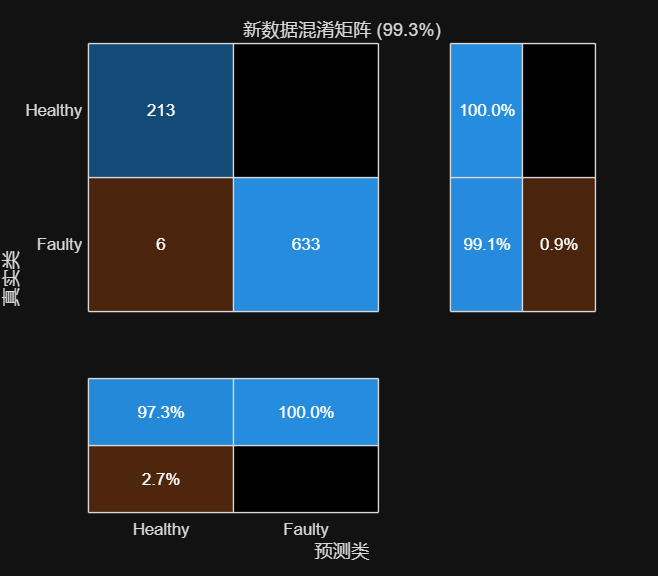


% 混淆矩阵
figure('Position',[100 100 800 700]);
cm = confusionchart(YAll(validIdx), YPred(validIdx), ...
    'Title', sprintf('新数据混淆矩阵 (%.1f%%)', acc*100), ...
    'RowSummary','row-normalized','ColumnSummary','column-normalized');
saveas(gcf, fullfile(outputDir,'混淆矩阵.png'));


% 分类报告
[C, order] = confusionmat(YAll(validIdx), YPred(validIdx));
fprintf('\n分类报告:\n%-12s %-8s %-8s %-8s\n','类别','精确率','召回率','F1分数');


分类报告:
类别           精确率      召回率      F1分数    


for i = 1:numel(order)
    TP = C(i,i); FP = sum(C(:,i))-TP; FN = sum(C(i,:))-TP;
    prec = TP/(TP+FP+eps); rec = TP/(TP+FN+eps); f1 = 2*prec*rec/(prec+rec+eps);
    fprintf('%-12s %-8.4f %-8.4f %-8.4f\n', string(order(i)), prec, rec, f1);
end

Healthy      0.9726   1.0000   0.9861  
Faulty       1.0000   0.9906   0.9953  


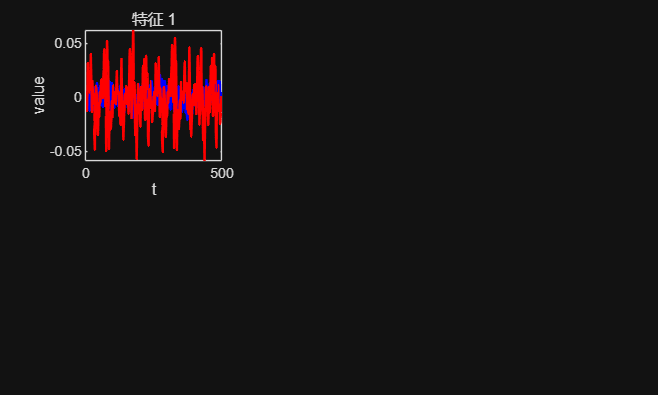

特征对比图失败: 



% 特征对比图
try
    c1 = YAll == order(1); c2 = YAll == order(2);
    if any(c1) && any(c2)
        mean1 = mean(XAll(:,:,:,c1),4,'omitnan');
        mean2 = mean(XAll(:,:,:,c2),4,'omitnan');
        fig = figure('Position',[200 200 1000 600]);
        for i = 1:6
            subplot(2,3,i);
            plot(squeeze(mean1(:,i,1)),'b','LineWidth',1.5); hold on;
            plot(squeeze(mean2(:,i,1)),'r','LineWidth',1.5);
            title(sprintf('特征 %d',i)); xlabel('t'); ylabel('value');
            legend(order(1),order(2),'Location','best'); grid on;
        end
        sgtitle(sprintf('%s vs %s 特征对比',order(1),order(2)));
        saveas(fig, fullfile(outputDir,'特征对比图.png'));
    end
catch ME
    fprintf('特征对比图失败: %s\n', ME.message);
end


%% 9. 保存结果
save(fullfile(outputDir,'测试结果.mat'), 'YPred','YAll','scores','acc');
T = table(YAll, YPred, max(scores,[],2), ...
    'VariableNames',{'TrueLabel','PredictedLabel','Confidence'});
writetable(T, fullfile(outputDir,'预测结果.csv'));
fprintf('\n全部完成！结果已保存至: %s\n', outputDir);


全部完成！结果已保存至: E:\FILE2\sheffeild\毕设\测试结果
